# Experiment 5.1

## Name: 

## Objectives

To verify the equivalency of the basic forms, including cascade, parallel, and feedback forms. To verify the equivalency of the basic moves, including moving blocks past summing junctions, and moving blocks past pickoff points.  

### Minimum Required Software Packages

MATLAB, Simulink, and the Control System Toolbox.

## Prelab

### Problem 1

*Find the equivalent transfer function of three cascaded blocks, *$G_1(s) = \frac{1}{s+1}$*, *$G_2(s) = \frac{1}{s+4}$*, and *$G_3(s) = \frac{s+1}{s+5}$*.*

**Answer:**

### Problem 2

*Find the equivalent transfer function of three parallel blocks, *$G_1(s) = \frac{1}{s+4}$*, *$G_2(s) = \frac{1}{s+4}$*, and *$G_3(s) = \frac{s+3}{s+5}$*.*

**Answer:**

### Problem 3

*Find the equivalent transfer funciton of the negative feedback system of Figure P5.55 (picture below) if *$G(s) = \frac{s+1}{s(s+2)}$*, and *$H(s)=\frac{s+3}{s+4}$*.*

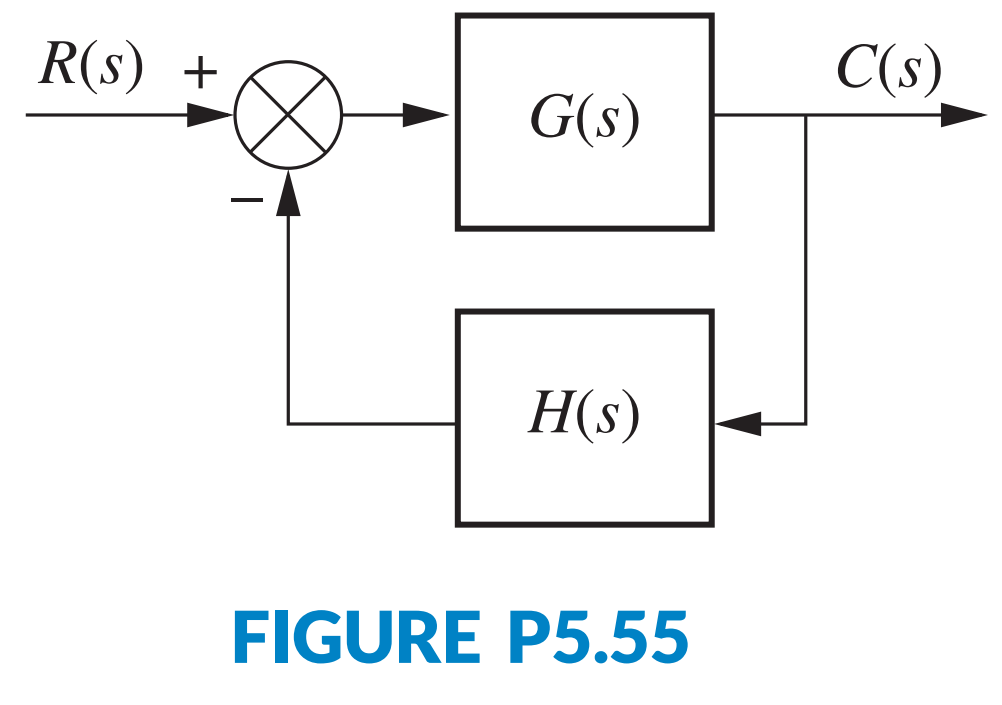

**Answer:**

### Problem 4

*For the system of **Prelab 3**, push *$H(s)$* to the left past the summing junction and draw the equivalent system.*

**Answer:**

### Problem 5

*For the system of **Prelab 3**, push *$H(s)$* to the right past the pickoff point and draw the equivalent system. *

**Answer:**

## Lab

### Problem 1

*Using Simulink, set up the cascade system of **Prelab 1** and the equivalent single block. Make separate plots of the step response of the cascaded system and its equivalent single block. Record the values of settling time and rise time for each step response.  *

*For your Simulink, please provide a screenshot that **clearly** shows the system.*

fc = 0;

### Problem 2

*Using Simulink, set up the parallel system of **Prelab 2** and the equivalent single block. Make separate plots of the step response of the parallel system and its equivalent single block. Record the values of settling time and rise time for each step response.  *

*For your Simulink, please provide a screenshot that **clearly** shows the system.*

% Insert your code here

### Problem 3

*Using Simulink, set up the negative feedback system of **Prelab 3** and the equivalent single block. Make separate plots of the step response of the negative feedback system and its equivalent single block. Record the values of settling time and rise time for each step response.  *

*For your Simulink, please provide a screenshot that **clearly** shows the system.*

% Insert your code here

### Problem 4

*Using Simulink, set up the negative feeback systems of **Prelab 3**, **Prelab 4**, and **Prelab 5**. Make separate plots of the step response of each of the systems. Record the values of settling time and rise time for each step response.  *

*For your Simulink, please provide a screenshot that **clearly** shows the system.*

*Prelab 3*

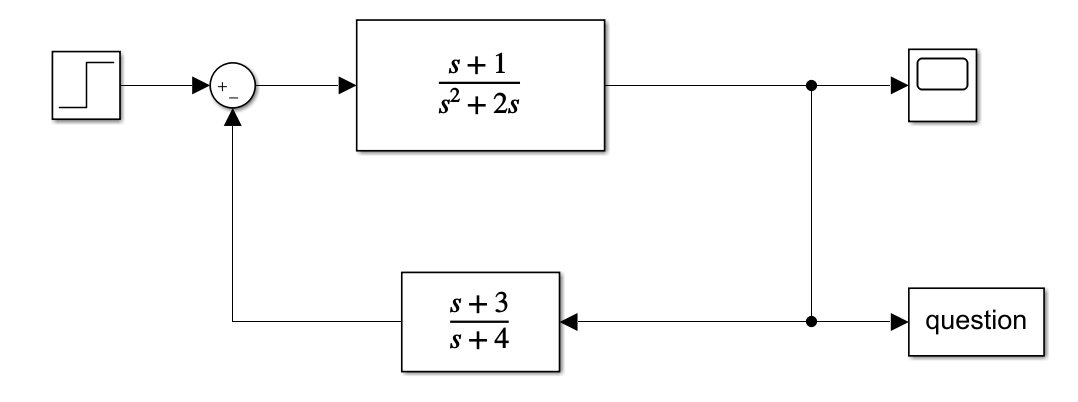

Prelab 4

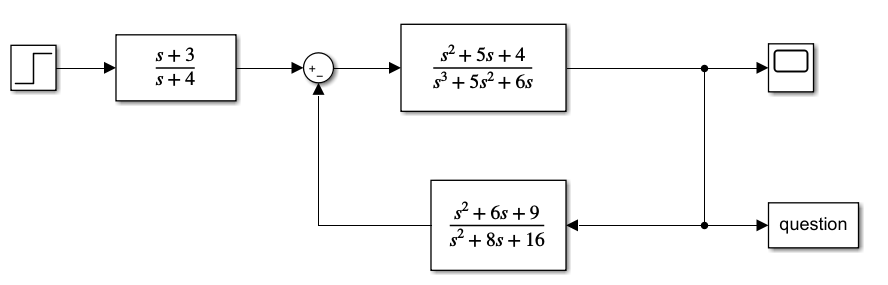

Prelab 5

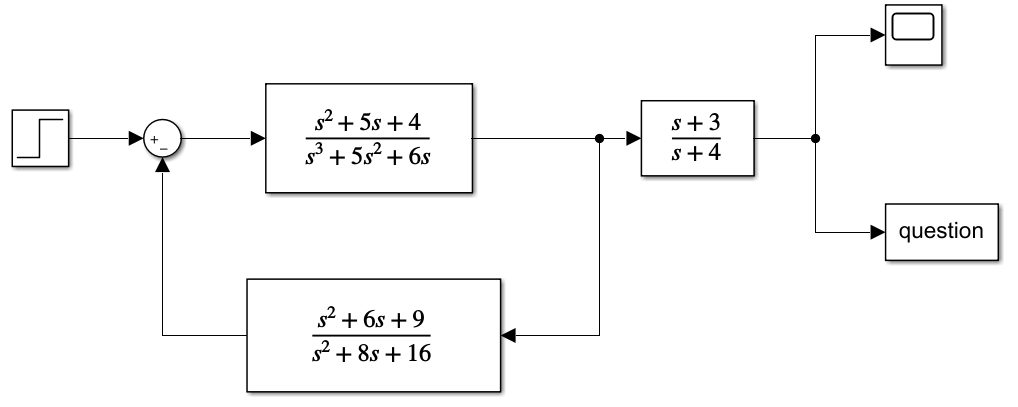

%Prelab 3
fc=fc+1; figure(fc);
subplot(3,1,1);
simOut = sim('Part43In.slx','ReturnWorkspaceOutputs','on');
disp("Prelab 3")

Prelab 3


stepinfo(simOut.question.Data, simOut.question.Time)

ans = struct with fields:
        RiseTime: 5.7635
    SettlingTime: 8.6876
     SettlingMin: 1.1523
     SettlingMax: 1.2803
       Overshoot: 0
      Undershoot: 0
            Peak: 1.2803
        PeakTime: 10


plot(simOut.question.Time, simOut.question.Data)
title("Original Function (Prelab 3)")

%Prelab 4
subplot(3,1,2)
simOut = sim('Part44Out.slx','ReturnWorkspaceOutputs','on');
disp("Prelab 4")

Prelab 4


stepinfo(simOut.question.Data, simOut.question.Time)

ans = struct with fields:
        RiseTime: 5.7635
    SettlingTime: 8.6876
     SettlingMin: 1.1523
     SettlingMax: 1.2803
       Overshoot: 0
      Undershoot: 0
            Peak: 1.2803
        PeakTime: 10


plot(simOut.question.Time, simOut.question.Data)
title("h(s) Pulled Left (Prelab 4)")

%Prelab 5
subplot(3,1,3)
simOut = sim('Part45Out.slx','ReturnWorkspaceOutputs','on');
disp("Prelab 5")

Prelab 5


stepinfo(simOut.question.Data, simOut.question.Time)

ans = struct with fields:
        RiseTime: 5.7635
    SettlingTime: 8.6876
     SettlingMin: 1.1523
     SettlingMax: 1.2803
       Overshoot: 0
      Undershoot: 0
            Peak: 1.2803
        PeakTime: 10


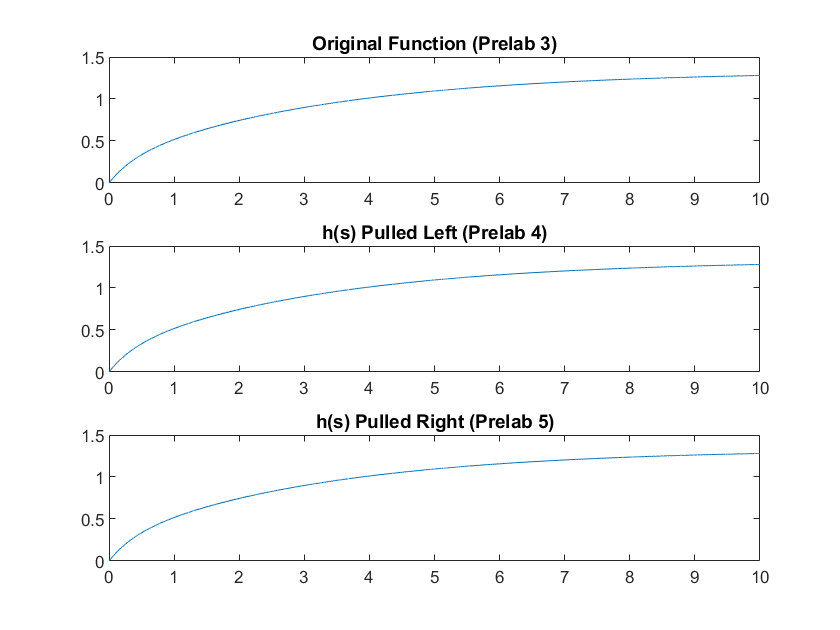

plot(simOut.question.Time, simOut.question.Data)
title("h(s) Pulled Right (Prelab 5)")

## Postlab

### Problem 1

*Using your lab data, verify the equivalent transfer function of blocks in cascade.*

### Problem 2

*Using your lab data, verify the equivalent transfer function of block in parallel.*

### Problem 3

*Using your lab data, verify the equivalent transfer function of negative feedback systems.*

### Problem 4

*Using your lab data, verify the moving of blocks past summing junctions and pickoff points.*

### Problem 5

*Discuss your results. Were the equivalencies verified?*